N = 10;
n = N^2;
rng(0);
A = gallery('poisson',N);
b = randn(n,1);
x0 = zeros(n,1);
eps = 1e-8;
maxiter = 3000;

lmin = 4 - 4 * cos(pi * 1/(1+N));
lmax = 4 + 4 * cos(pi * 1/(1+N));

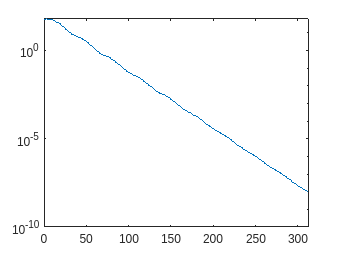

[x, res] = tschebyscheff(A, b, x0, lmin, lmax, maxiter, eps);
figure
semilogy(res)
hold on

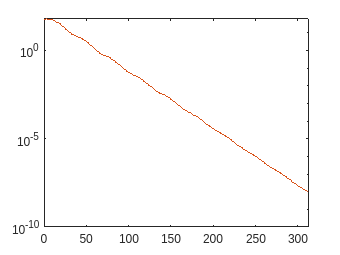

[x, res] = tschebyscheff2(A, b, x0, lmin, lmax, maxiter, eps);
semilogy(res);

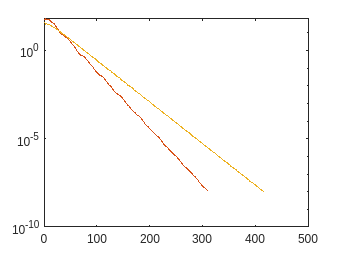

[x, res] = tschebyscheff2(A, b, x0, lmin, 2 * lmax, maxiter, eps);
semilogy(res);

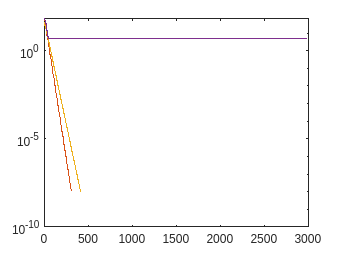

%[x, res] = tschebyscheff2(A, b, x0, lmin, lmax - lmin, maxiter, eps);
%semilogy(res);

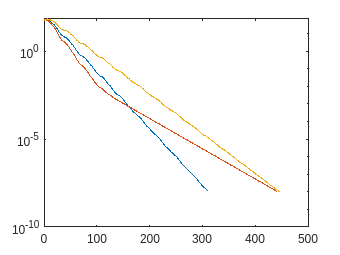

[x, res] = tschebyscheff2(A, b, x0, lmin* 0.5, lmax, maxiter, eps);
semilogy(res);

gamma = (lmax - lmin)/(lmax + lmin);
omega = 2 /(1 + sqrt(1 - gamma * gamma))

omega = 1.5604

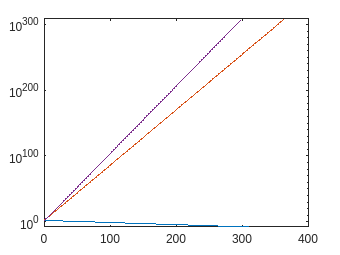

%omega = 1;
[x, res] = richardson2ndorder(A, b, x0, omega, maxiter, eps);
semilogy(res);

clc